# Star Secular Determinant

Computes analytical and numerical secular determinants and compares the results with each other as well as the squareroots of the eigenvalues.

### Create the graph

Creates the graph with both the uniform and Chebyshev discretizations so we can compare the eigenvalues of these two discretizations later

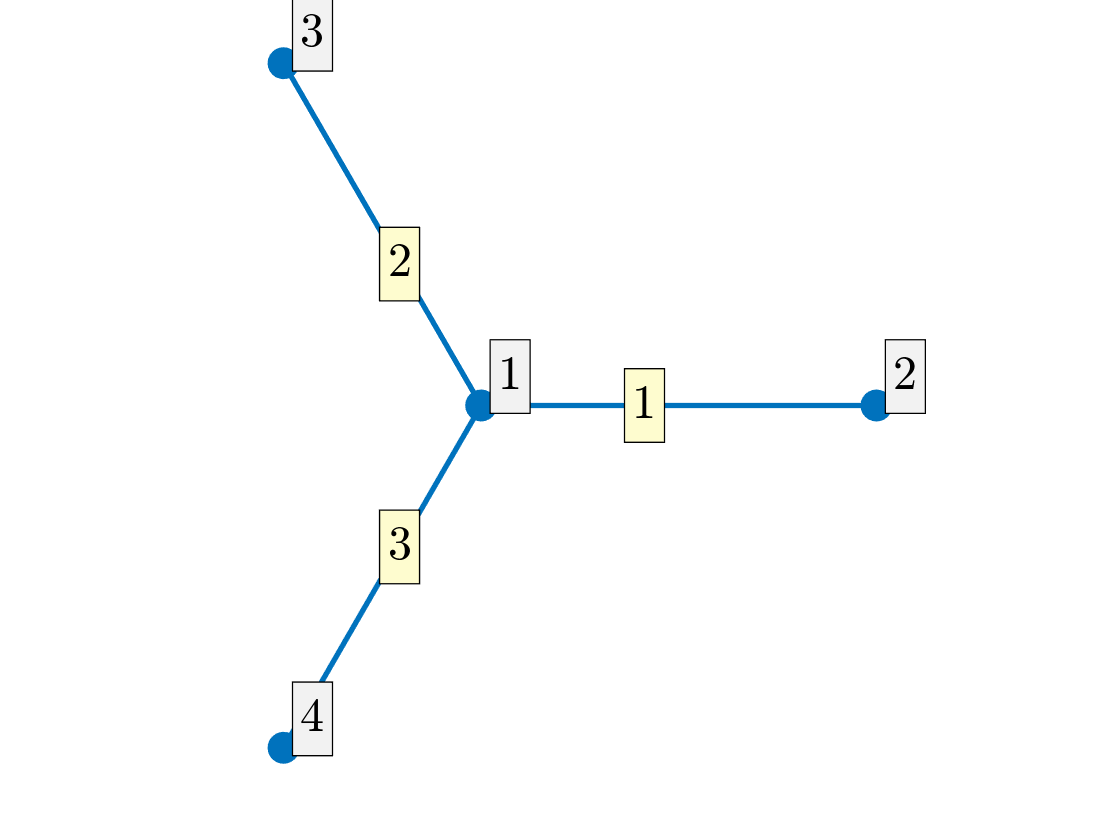

syms k
clf;
alpha = -1;
robinCoeff = [alpha 0 0 0];
Phi = quantumGraphFromTemplate('star','robinCoeff',robinCoeff,'discretization','Chebyshev','nx',8);
PhiU = quantumGraphFromTemplate('star','robinCoeff',robinCoeff,'discretization','Uniform','nx',64);
Phi.plot('layout')

## Numerical Secular Determinant

This converts the symbolic numerical secular determinant to a Matlab function then plots it and it's zeros

[SD,S,D] = Phi.secularDet;
disp('The numerical secular determinant is:')

The numerical secular determinant is:


disp(SD)

$$-\frac{{\cos\left(\pi \,x\right)}^{2}\,\left(\cos\left(\pi \,x\right)-3\,x\,\sin\left(\pi \,x\right)\right)}{3\,\sqrt{9\,x^{2}+1}}$$

disp('The corresponding S matrix is:')

The corresponding S matrix is:


disp(S)

$$\begin{array}{l} \left(\begin{array}{cccccc} 0 & 0 & 0 & \sigma_{1}-1 & \sigma_{1} & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & \sigma_{1}-1 & \sigma_{1}\\ 0 & 0 & 0 & \sigma_{1} & \sigma_{1} & \sigma_{1}-1\\ 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2}{3+\frac{\mathrm{i}}{x}} \end{array}$$

(I should point out that this S matrix matches my analytic results.)

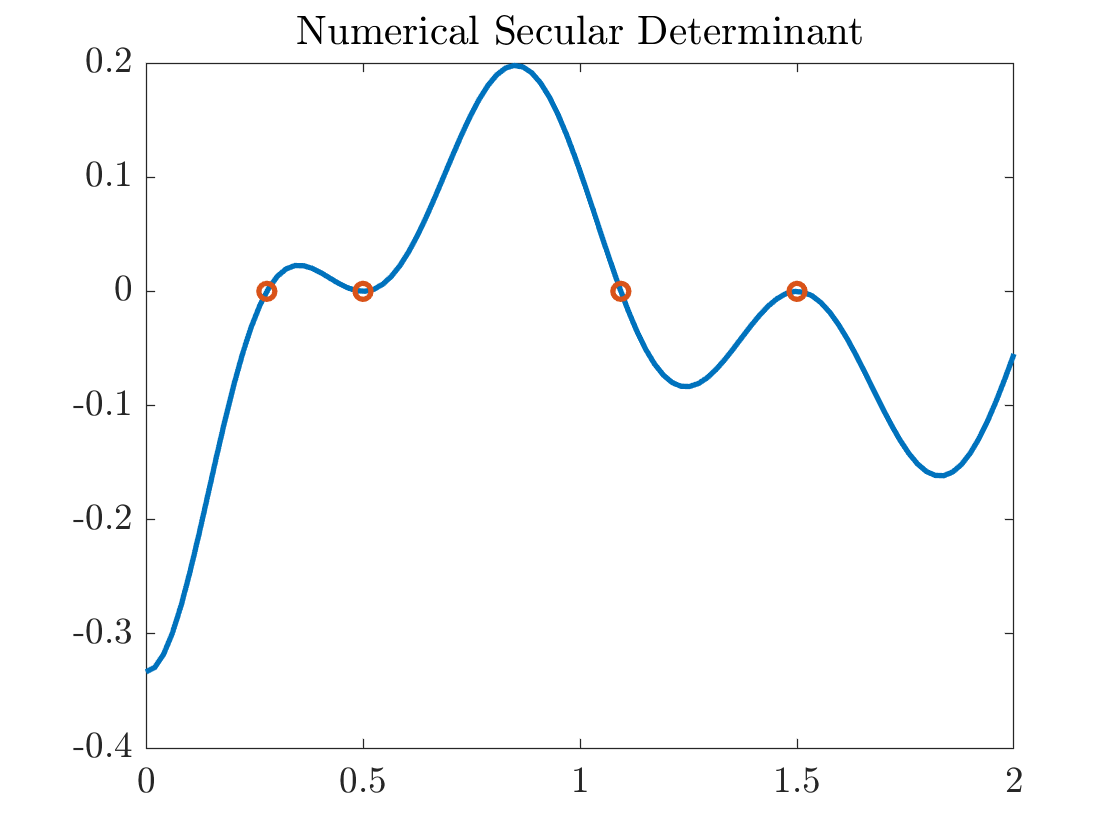

F=matlabFunction(SD);
x=linspace(0,2);
Fx=F(x);
clf
plot(x,Fx) 
title('Numerical Secular Determinant')

% Finds zeros of F(x)
kmax=2;
signChanges=find(Fx(1:end-1).*Fx(2:end)<0);
nSignChanges=length(signChanges);
kstar=zeros(nSignChanges,1);
for n=1:nSignChanges
    kstar(n)=fzero(F,x(signChanges(n)+[0 1]));
end
doubleRoots=(1/2):1:kmax;
kstar=union(kstar,doubleRoots);
hold on
plot(kstar,zeros(size(kstar)),'o')

lambdaNumerical = kstar.^2;

## Analytical Secular Determinant

This converts the symbolic analytical secular determinant to a Matlab function then plots it and it's zeros

analyticSD = (3*k*sin(k*pi)+alpha* cos(k*pi))*cos(k*pi)^2; %(8i*(cos(k)^2)*(cos(k)-3*k*sin(k))*(cos(3*k)+1i*sin(3*k)))/(1i+3*k); % L=1
disp('The analytic secular determinant is:')

The analytic secular determinant is:


disp(analyticSD)

$$-{\cos\left(\pi \,k\right)}^{2}\,\left(\cos\left(\pi \,k\right)-3\,k\,\sin\left(\pi \,k\right)\right)$$

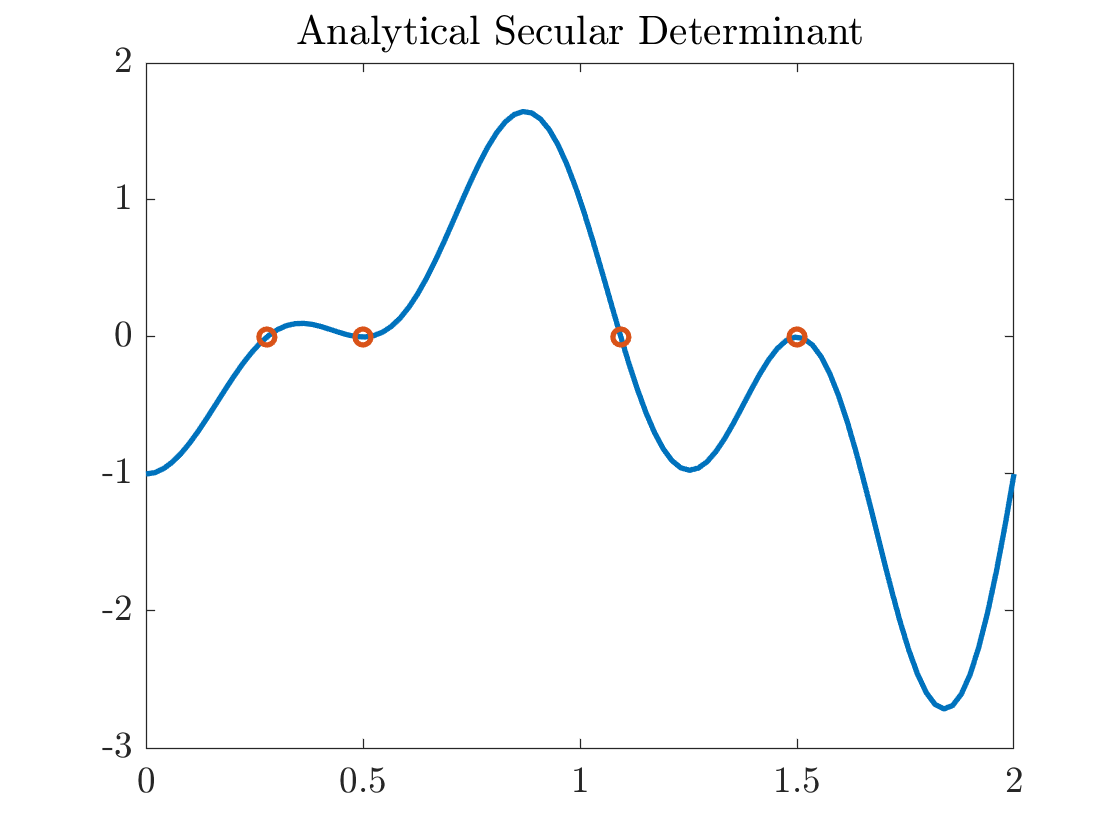

analyticF = matlabFunction(analyticSD);
analyticFx = analyticF(x);
figure
plot(x,analyticFx)
title('Analytical Secular Determinant')

% Finds zeros of F(x)
signChangesA=find(analyticFx(1:end-1).*analyticFx(2:end)<0);
nSignChangesA=length(signChangesA);
kstarA=zeros(nSignChangesA,1);
for n=1:nSignChangesA
    kstarA(n)=fzero(analyticF,x(signChangesA(n)+[0 1]));
end
doubleRootsA=(1/2):1:kmax;
kstarA=union(kstarA,doubleRootsA);
hold on
plot(kstarA,zeros(size(kstarA)),'o')

lambdaAnalytic = kstarA.^2;

We then create a plot comparing the two secular determinants and their roots.

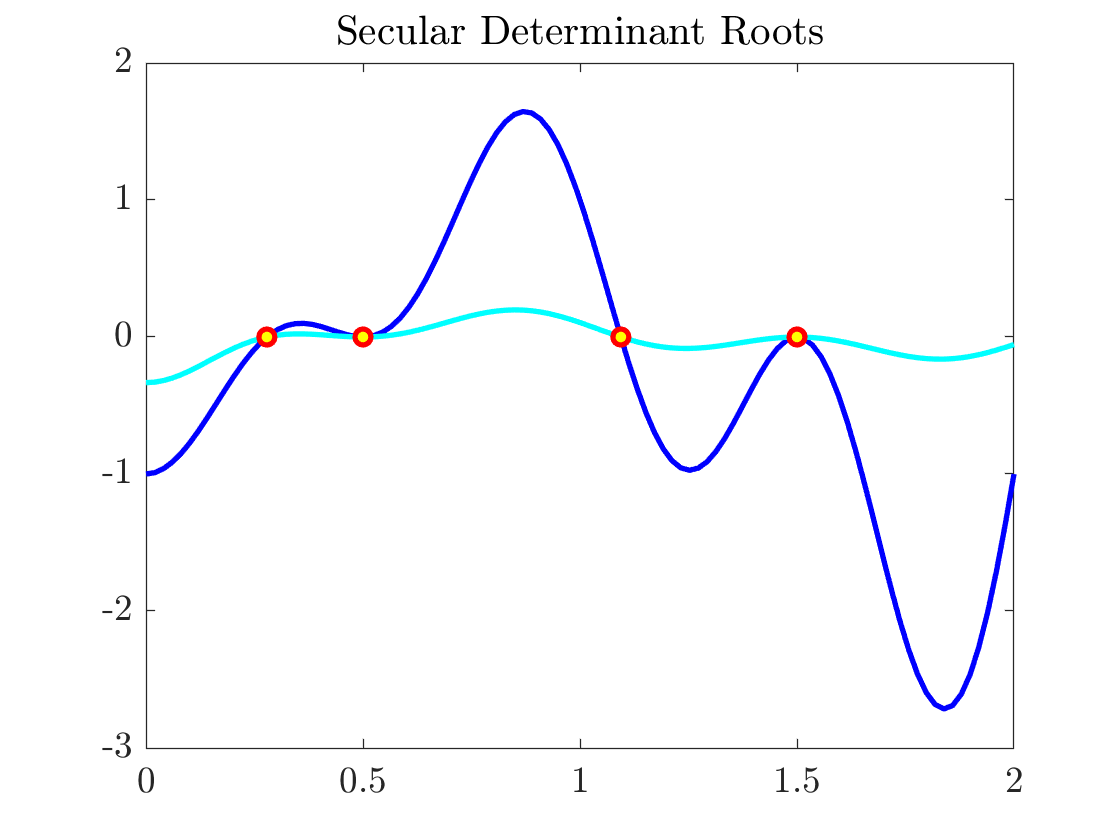

figure
plot(x,analyticFx,'color','b')
title('Secular Determinant Roots')
hold on
plot(x,Fx,'color','cyan')
hold on
plot(kstar,zeros(size(kstar)),'*','color','y')
hold on
plot(kstarA,zeros(size(kstarA)),'o','color','r')

## Compares secular determinant to Laplacian eigenvalues

Table of found lambda values. The column labels are shorthand for:

NSD: evals from the numerical SD

ASD: evals from the analytical SD

Cheb: evals from Chebyshev Laplacian

Uni: evals from uniform Laplacian

[~,lambda] = eigs(Phi,5);
lambda = uniquetol(lambda);
sqrt(lambda);
[~,lambdaU] = eigs(PhiU,5);
lambdaU = uniquetol(lambdaU);
lambdaU = -flip(lambdaU);
sqrt(lambdaU);

A = [lambdaNumerical'; lambdaAnalytic'; lambda'; lambdaU'];

T = array2table(A','VariableNames', ...
    {'NSD','ASD','Cheb','Uni'})

T = 4×4 table
      NSD         ASD         Cheb        Uni   
    ________    ________    ________    ________

    0.077545    0.077545    0.077545    -0.46916
        0.25        0.25        0.25        0.25
      1.1971      1.1971      1.1971     0.59843
        2.25        2.25        2.25      2.2499


Compare zeros of SD (represented on plot) to the sqrt of the evals. They should be the same!

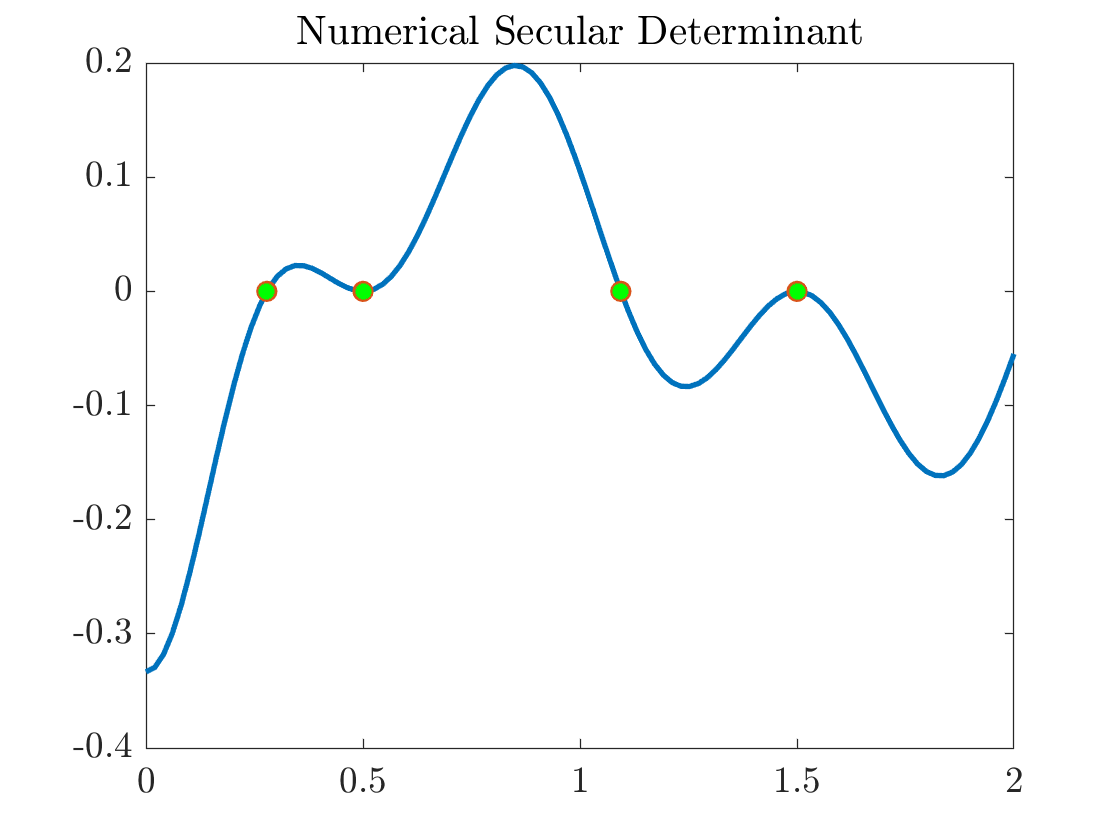

figure
plot(x,Fx)
title('Numerical Secular Determinant')
hold on
plot(kstar,zeros(size(kstar)),'o')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')

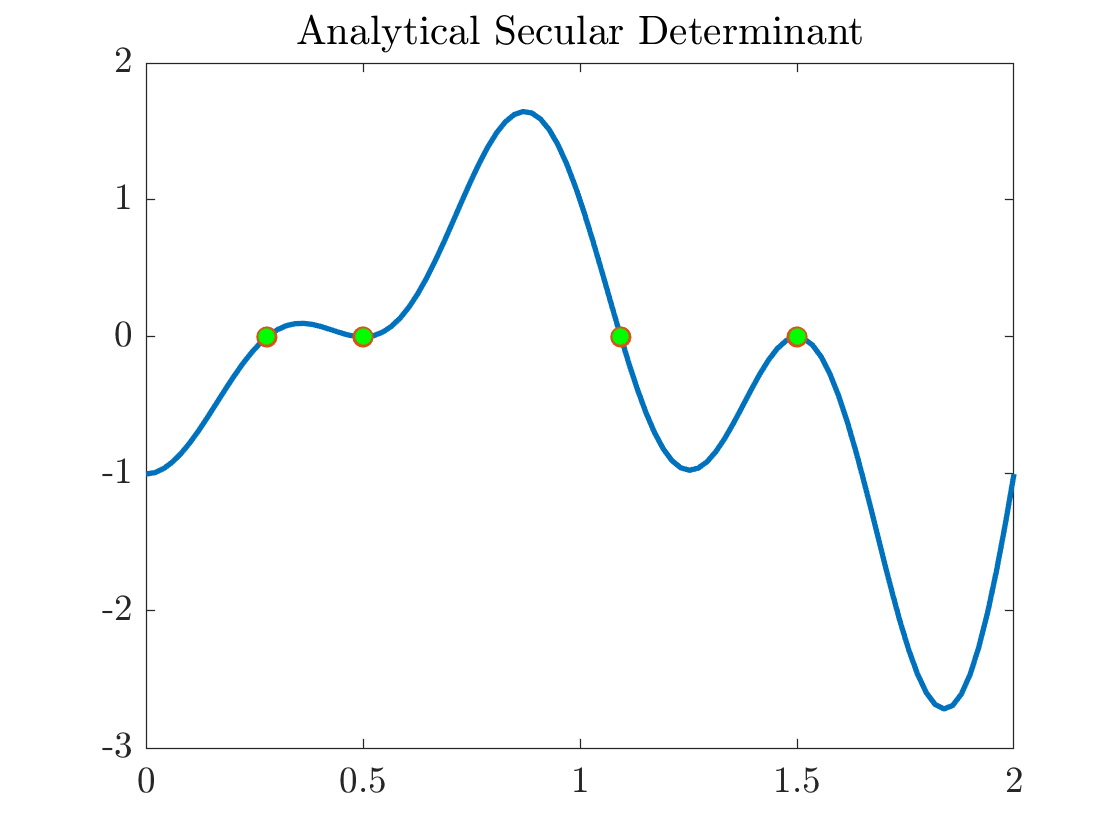



figure
plot(x,analyticFx)
title('Analytical Secular Determinant')
hold on
plot(kstarA,zeros(size(kstarA)),'o')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')